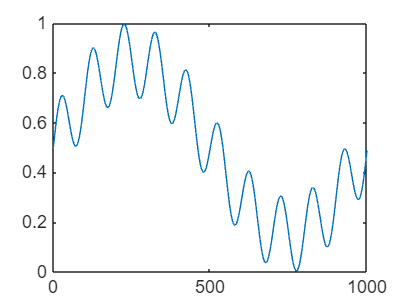

clear all

f1 = 1;
f2 = 10;
Vf1 = 0.7;
Vf2 = 1-Vf1;
Vref = 3.3;
N = 16;
Vlsb = Vref/(2^N);
dt = 0.001;
t = [0:dt:1/f1-dt];
y = (Vf1*sin(2*pi*f1*t)+Vf2*(sin(2*pi*f2*t))+1)*1/2;
plot(y)

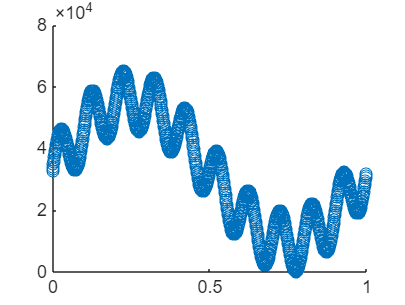


y_hex = floor(y*(2^N-1));
scatter(t,y_hex)


hex_sine = dec2hex(y_hex)

hex_sine = 1000×4 char array
    '7FFF'
    '82F8'
    '85EF'
    '88E1'
    '8BCC'
    '8EAD'
    '9182'
    '9449'
    '96FF'
    '99A3'
    '9C31'
    '9EA9'
    'A108'
    'A34C'
    'A574'
    'A77E'
    'A969'
    'AB33'
    'ACDA'
    'AE5F'
    'AFBF'
    'B0FA'
    'B210'
    'B2FF'
    'B3C8'
    'B469'
    'B4E4'
    'B538'
    'B566'
    'B56D'
    'B54E'
    'B50A'
    'B4A2'
    'B417'
    'B36A'
    'B29B'
    'B1AD'
    'B0A1'
    'AF79'
    'AE36'
    'ACD9'
    'AB66'
    'A9DE'
    'A843'
    'A697'
    'A4DC'
    'A315'
    'A145'
    '9F6C'
    '9D8F'
    '9BAF'
    '99CF'
    '97F1'
    '9617'
    '9444'
    '927B'
    '90BD'
    '8F0E'
    '8D6E'
    '8BE1'
    '8A69'
    '8907'
    '87BD'
    '868D'
    '857A'
    '8484'
    '83AD'
    '82F6'
    '8261'
    '81EF'
    '81A0'
    '8176'
    '8171'
    '8192'
    '81D9'
    '8246'
    '82DA'
    '8394'
    '8474'
    '8579'
    '86A4'
    '87F3'
    '8966'
    '8AFC'
    '8CB3'
    '8E8A'
    '9080'
    '9294'
   

MSB = bitshift(y_hex,-8) 

MSB =    127   130   133   136   139   142   145   148   150   153   156   158   161   163   165   167   169   171   172   174   175   176   178   178   179   180   180   181   181   181   181   181   180   180   179   178   177   176   175   174   172   171   169   168   166   164   163   161   159   157


msb_sine = "0x"+string(dec2hex(MSB))

msb_sine = 1000×1 string array
    "0x7F"
    "0x82"
    "0x85"
    "0x88"
    "0x8B"
    "0x8E"
    "0x91"
    "0x94"
    "0x96"
    "0x99"
    "0x9C"
    "0x9E"
    "0xA1"
    "0xA3"
    "0xA5"
    "0xA7"
    "0xA9"
    "0xAB"
    "0xAC"
    "0xAE"
    "0xAF"
    "0xB0"
    "0xB2"
    "0xB2"
    "0xB3"
    "0xB4"
    "0xB4"
    "0xB5"
    "0xB5"
    "0xB5"


lsb_sine = "0x"+string(dec2hex(y_hex-MSB*2^8))

lsb_sine = 1000×1 string array
    "0xFF"
    "0xF8"
    "0xEF"
    "0xE1"
    "0xCC"
    "0xAD"
    "0x82"
    "0x49"
    "0xFF"
    "0xA3"
    "0x31"
    "0xA9"
    "0x08"
    "0x4C"
    "0x74"
    "0x7E"
    "0x69"
    "0x33"
    "0xDA"
    "0x5F"
    "0xBF"
    "0xFA"
    "0x10"
    "0xFF"
    "0xC8"
    "0x69"
    "0xE4"
    "0x38"
    "0x66"
    "0x6D"



mcu_sin = [msb_sine,lsb_sine]

mcu_sin = 1000×2 string array
    "0x7F"    "0xFF"
    "0x82"    "0xF8"
    "0x85"    "0xEF"
    "0x88"    "0xE1"
    "0x8B"    "0xCC"
    "0x8E"    "0xAD"
    "0x91"    "0x82"
    "0x94"    "0x49"
    "0x96"    "0xFF"
    "0x99"    "0xA3"
    "0x9C"    "0x31"
    "0x9E"    "0xA9"
    "0xA1"    "0x08"
    "0xA3"    "0x4C"
    "0xA5"    "0x74"
    "0xA7"    "0x7E"
    "0xA9"    "0x69"
    "0xAB"    "0x33"
    "0xAC"    "0xDA"
    "0xAE"    "0x5F"
    "0xAF"    "0xBF"
    "0xB0"    "0xFA"
    "0xB2"    "0x10"
    "0xB2"    "0xFF"
    "0xB3"    "0xC8"
    "0xB4"    "0x69"
    "0xB4"    "0xE4"
    "0xB5"    "0x38"
    "0xB5"    "0x66"
    "0xB5"    "0x6D"


mcu_sin_reshaped = reshape(mcu_sin',1,[])

mcu_sin_reshaped = 1×2000 string array
    "0x7F"    "0xFF"    "0x82"    "0xF8"    "0x85"    "0xEF"    "0x88"    "0xE1"    "0x8B"    "0xCC"    "0x8E"    "0xAD"    "0x91"    "0x82"    "0x94"    "0x49"    "0x96"    "0xFF"    "0x99"    "0xA3"    "0x9C"    "0x31"    "0x9E"    "0xA9"    "0xA1"    "0x08"    "0xA3"    "0x4C"    "0xA5"    "0x74"    "0xA7"    "0x7E"    "0xA9"    "0x69"    "0xAB"    "0x33"    "0xAC"    "0xDA"    "0xAE"    "0x5F"    "0xAF"    "0xBF"    "0xB0"    "0xFA"    "0xB2"    "0x10"    "0xB2"    "0xFF"    "0xB3"    "0xC8"    "0xB4"    "0x69"    "0xB4"    "0xE4"    "0xB5"    "0x38"    "0xB5"    "0x66"    "0xB5"    "0x6D"    "0xB5"    "0x4E"    "0xB5"    "0x0A"    "0xB4"    "0xA2"    "0xB4"    "0x17"    "0xB3"    "0x6A"    "0xB2"    "0x9B"    "0xB1"    "0xAD"    "0xB0"    "0xA1"    "0xAF"    "0x79"    "0xAE"    "0x36"    "0xAC"    "0xD9"    "0xAB"    "0x66"    "0xA9"    "0xDE"    "0xA8"    "0x43"    "0xA6"    "0x97"    "0xA4"    "0xDC"    "0xA3"    "0x15"    "0xA1"    "0x45" 


folder = "C:\Users\Peter\STM32CubeIDE\workspace_1.12.0\RedPill_DAC_SPI_Meas_MultiSin_Opt\Core\Src\";
fid = fopen(folder+"dacMultiSine.txt",'wt');
fprintf(fid,'%s,', mcu_sin_reshaped{1:end-1});
fprintf(fid,'%s', mcu_sin_reshaped{end});
fclose(fid);

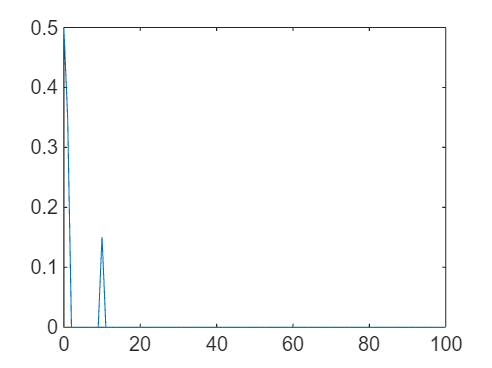

% FFT of the generated signal

Y = abs(fft(y))/length(t);
df = (1/(length(t)*dt));
f = [0:df:(1/dt)-df];
f_egy = f(1:end/2);
Y(2:end) = 2*Y(2:end);
Y_egy = Y(1:end/2);
plot(f_egy,Y_egy)
xlim([0,100])

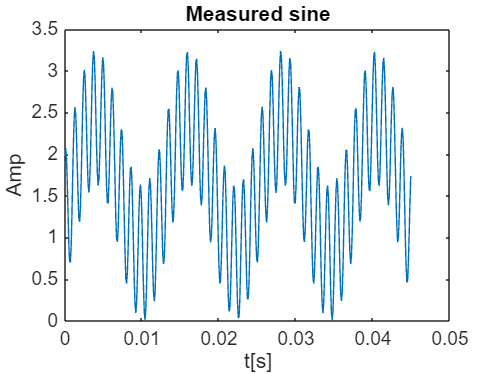

% Processing the data !!!!

% dac2SinFs1000Hz and dac2SinFs10kHz contains the data of the measured 2
% component sine. 5 columns are 5 differents measurements

clear all

file1k = 'dac2SinFs1000Hz.xlsx';
file10k = 'dac2SinFs10kHz.xlsx';
fs_1k = 1000;
fs_10k = 10000;

T = readtable(file10k,'Sheet','0.5','ReadVariableNames', false);
y = T{:,1}';

fs = fs_10k;
dt = 1/fs;
N = length(y);
t = [0:dt:N*dt-dt];

figure()
plot(t,y)
title('Measured sine')
xlabel('t[s]')
ylabel('Amp')

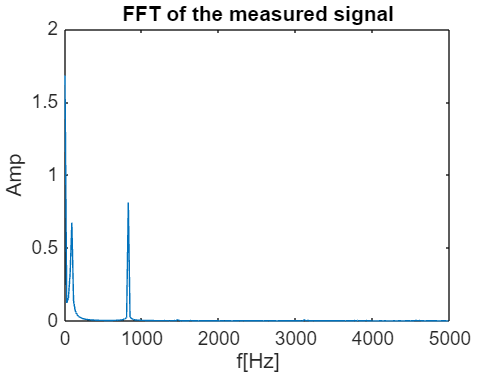

% FFT

Y = abs(fft(y))/length(t);
df = (1/(length(t)*dt));
f = [0:df:(1/dt)-df];
f_egy = f(1:end/2);
Y(2:end) = 2*Y(2:end);
Y_egy = Y(1:end/2);

figure()
plot(f_egy,Y_egy)
title('FFT of the measured signal')
xlabel('f[Hz]')
ylabel('Amp')

% 2 component LSM
f1 = 100; % based on the spectre
f2 = 1000;

%least square method
n = length(y);
D = [cos(2*pi*f1*t)',sin(2*pi*f1*t)',cos(2*pi*f2*t)',sin(2*pi*f2*t)', ones(n,1)]; %trig identity to cos + sin for phase
DD = D'*D;
K = DD\D'*y' % least square

K =   -0.018904571177685
  -0.222367893539216
  -0.004114392622033
   0.000745789560343
   1.698037768166999


R1_est = sign(K(1))*sqrt(K(1)^2+K(2)^2)

R1_est =   -0.223170031340412


R2_est = sign(K(3))*sqrt(K(3)^2+K(4)^2)

R2_est =   -0.004181438594139


fi1_est = atan(-K(2)/K(1))+pi/2 

fi1_est =    0.084810909337633


fi2_est = atan(-K(4)/K(3))+pi/2 

fi2_est =    1.750112925353804
